# Short introduction to the Generalized Extreme Values (GEV) distribution

##  Summary

In this script, some of the results presented by John D. Holmes in the first part of the chapter 2 of his book [1] are reproduced .  The notations used in[1] differ slightly from those used with the Matlab statistics toolbox. In particular, the expression of the cumulative density function of the GEV he uses is based on the shape factor k whereas the statistical toolbox uses "K = -k". To keep consistent with the Matlab notations, the convention "K = -k" is also used herein.

####  **References**

 [1] Holmes, J. D. (2015). Wind loading of structures. CRC Press.

## Example 1

 The figure plotted here reproduces the one shown in Fig 2.1 in [1]

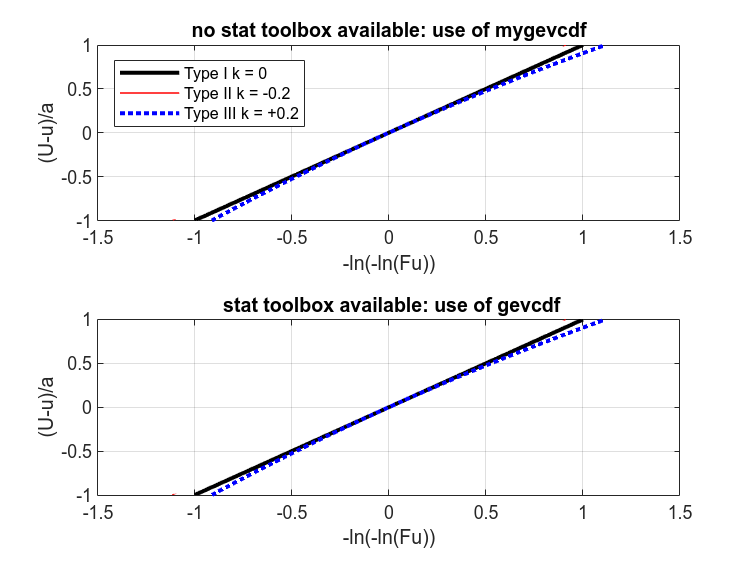

clearvars;close all;clc;
K = [0,0.2,-0.2]; % 3 types of GEV distributions (K<0, K=0 and K>0)
N = 100;
a = 1;
u = 1;
U = linspace(0,2,N); 
% Check if statistic toolbox exists
status = license('test','statistics_toolbox');if status==0, warning('No satistics toolbox detected');end

F = zeros(3,N);
for ii=1:numel(K)
    F(ii,:) = mygevcdf(U,K(ii),a,u); % if no stat toolbox available
end

clf;close all;figure
tiledlayout('flow')
nexttile
hold on;box on;
plot(-log(-log(F(1,:))),(U-u)./a,'k','linewidth',2);
plot(-log(-log(F(2,:))),(U-u)./a,'r','linewidth',0.7);
plot(-log(-log(F(3,:))),(U-u)./a,'b:','linewidth',2);
grid on
xlabel('-ln(-ln(Fu))')
ylabel('(U-u)/a')
legend('Type I k = 0','Type II k = -0.2','Type III k = +0.2',...
    'location','Northwest')
title('no stat toolbox available: use of mygevcdf')

if status ==1
    F = zeros(3,N);
    for ii=1:3
        F(ii,:)  = gevcdf(U,K(ii),a,u); % if stat toolbox is available
    end
    nexttile
    hold on;box on;
    plot(-log(-log(F(1,:))),(U-u)./a,'k','linewidth',2);
    plot(-log(-log(F(2,:))),(U-u)./a,'r','linewidth',0.7);
    plot(-log(-log(F(3,:))),(U-u)./a,'b:','linewidth',2);
    grid on
    xlabel('-ln(-ln(Fu))')
    ylabel('(U-u)/a')
    title(' stat toolbox available: use of gevcdf')
end


set(gcf,'color','w')

## Example 2

The data used (EastSale.mat) in this example comes from page 42-43 in [1]. The extreme 10  min win velocities are calculated for different return periods, and different methods. The matlab built-in function provided with the statistical toolbox is compared to the one used here.

load EastSale

method = ["GEVF"; "Gumbel";"moments";"Gringorten"]

method = 4×1 string array
    "GEVF"
    "Gumbel"
    "moments"
    "Gringorten"


parmhat = zeros(numel(method),3);
for ii=1:4
    if ii==1, % Matlab built-in function
        [parmhat(ii,:)] = gevfit(meanU);
    else % Home-made function
        [parmhat(ii,:)] = fitGEV(meanU,'method',method(ii));
    end
end
T = table(method,parmhat(:,1),parmhat(:,2),parmhat(:,3));
T.Properties.VariableNames = ["Method","k","mu","sigma"];
disp(T)

       Method           k           mu      sigma 
    ____________    __________    ______    ______

    "GEVF"          -0.0016612    2.4209    27.891
    "Gumbel"                 0     2.659    27.811
    "moments"                0    2.4923    27.827
    "Gringorten"             0    2.5127     27.84




% cdf of GEV
N = 1e4;
X = linspace(min(meanU),3*max(meanU),N); % Measured
F = zeros(numel(method),N);
R = zeros(numel(method),N);
clear ind*
returnP = [50 100 200 500 1000];
for ii=1:4
    F(ii,:)  = mygevcdf(X,parmhat(ii,1),parmhat(ii,2),parmhat(ii,3));
    % Return period R
    R(ii,:)= 1./(1-F(ii,:)); % Gumbel
    for jj=1:numel(returnP),
        [~,indMax(jj,ii)] = min(abs(R(ii,:)-returnP(jj)));
    end
end

fprintf('Prediction of extreme wind speeds for East Sale (synoptic winds): \n')

Prediction of extreme wind speeds for East Sale (synoptic winds): 


val = round(10*[[50 100 200 500 1000]',X(indMax)])/10;
T = table(val(:,1),val(:,2),val(:,3),val(:,4),val(:,5));
T.Properties.VariableNames = ["Ret. Period (years)",method'];
disp(T)

    Ret. Period (years)    GEVF    Gumbel    moments    Gringorten
    ___________________    ____    ______    _______    __________

             50            37.3     38.2      37.6         37.6   
            100              39       40      39.3         39.4   
            200            40.7     41.9        41         41.1   
            500            42.9     44.3      43.3         43.4   
           1000            44.5     46.2        45         45.2   



### Graphical visualization

This time the function mygevcdf is used in combination with fitGEV.

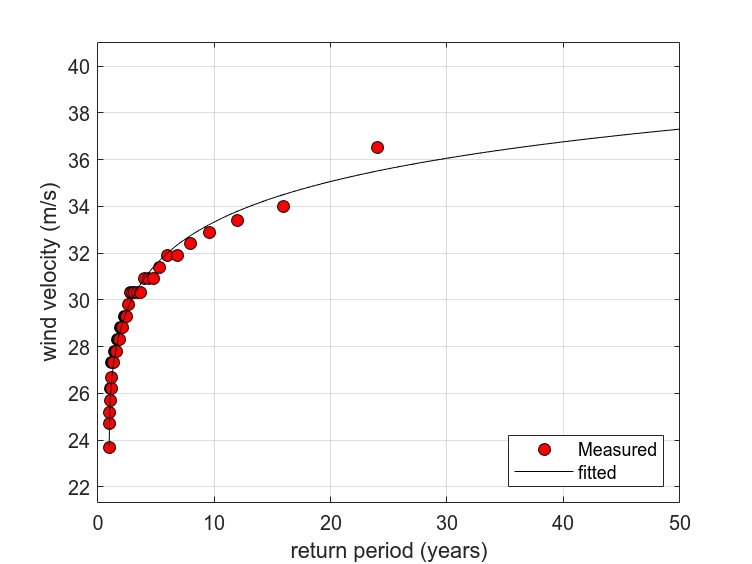

% get cdf
returnPeriod = 50;
x = ([1:numel(meanU)])/(numel(meanU)+1);
r = 1./(1-x);
X = linspace(min(meanU),2*max(meanU),1e4);
F  = mygevcdf(X,parmhat(1,1),parmhat(1,2),parmhat(1,3)); % for fitted parameters
R = 1./(1-F);

figure
hold on;box on;
plot(r,sort(meanU),'ko','markerfacecolor','r'); % cdf of meanU
plot(R,X,'k');
xlabel('return period (years)');
ylabel('wind velocity (m/s)');
axis tight
  ylim([0.9*min(X(R<returnPeriod)),1.1*max(X(R<returnPeriod))])
    xlim([0,returnPeriod])
legend('Measured','fitted','location','SouthEast')
grid on

set(gcf,'color','w');

It is actually possible to plot directly the figure using fitGEV:

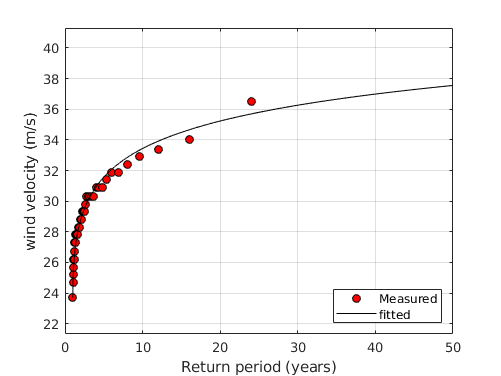

50-year hourly wind velocity is 37.6 m/s (based on 65 years of data) 


load EastSale
[parmhat2] = fitGEV(meanU,'method','moments','dataPlot',1,'returnPeriod',50);